# Chapter 10: Approximability Models

close all; clear all;

## Hilbert setting

Note that the observation map, denoted $\Lambda$ in the text, is denoted L here.

% generate the approximation space V and the observation map L
N = 40;                  % dimension of the ambient Hilbert space
n = 9;                   % dimension of the space V
epsilon = 0.1;           % the approximation parameter
V = randn(N,n);          % the columns of this matrix form a basis of the space V
V = V*inv(sqrtm(V'*V));  % the columns now form an orthornomal basis 
m = 22;                  % number of observations
L = randn(m,N);          % the observation map
% generate an element in the approximability set and its observation vector
aux = randn(N,1);
f = V*rand(n,1) + (2/3)*epsilon*aux/norm(aux);
y = L*f;

Produce the Chebyshev center $f^\star$ (according to Proposition 10.3) and the compatibility parameter $\mu$(according to Theorem 10.4).

% define the Gramian Gu and the cross-Gramian C (the Gramian Gv is the identity)
Gu = L*L';
C = L*V;
% produce f_star
Gu_inv = inv(Gu);
b = (C'*Gu_inv*C)\(C'*Gu_inv*y);
a = Gu_inv*(y-C*b);
f_star = L'*a + V*b;
% produce mu
mu = 1/sqrt(min(eig(C'*Gu_inv*C)));

Compute the local worst-case error at $f^\star$ by two different methods: 

- the one which is implicit in (10.7)-(10.8);

- the one, valid for an arbitrary $f$ instead of $f^\star$, which is to be found later in Exercise 23.2.

% the worst-case error using the first method
P1 = eye(N)-V*V';        % the orthogonal projector onto the orthogonal space to V 
wce1 = mu*sqrt(epsilon^2 - norm(P1*f_star)^2);
% the worst-case error using the second method 
[Q,R] = qr(L');
K = Q(:,m+1:N);          % the columns form an orthonormal basis for ker(L) 
P2 = K*inv(K'*K)*K';     % the orthogonal projector onto ker(L)
h = L'*((L*L')\y);       % the element orthogonal to ker(L) for which L(h)=y
cvx_begin quiet
variable c
variable d nonnegative
minimize c
subject to 
[K'*(d*P1-eye(N))*K, K'*(d*P1*h+P2*f_star);...
    (d*h'*P1+f_star'*P2)*K, c + d*( norm(P1*h)^2 - epsilon^2 )] == semidefinite(N-m+1)
cvx_end
wce2 = sqrt( norm(h-f_star+P2*f_star)^2 + norm(P2*f_star)^2 + c );
fprintf('The two worst-case errors are %.4f and %.4f: they are indeed identical.', wce1, wce2)

The two worst-case errors are 0.2305 and 0.2305: they are indeed identical.

## Real-valued quantity of interest

The example considered here consists of the optimal estimation of the integral of a univariate function $f \in C([-1,1])$ given its point values at $m$ equispaced points $x^{(1)},\ldots,x^{(m)} \in [-1,1]$. 

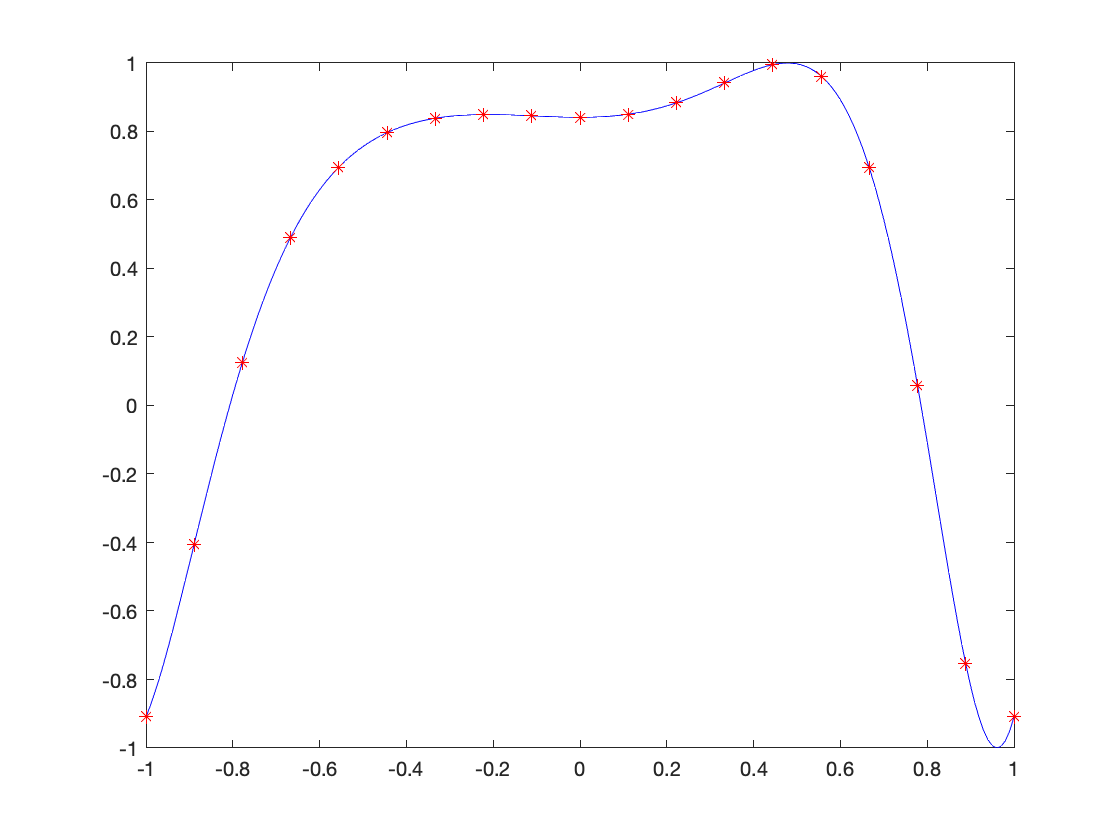

clear all;
% generate a function f and its vector of point values
f = @(x) sin(pi*x.^3+x.^2+1);
m = 19;
eqpts = linspace(-1,1,m);
y = f(eqpts);
grid = linspace(-1,1,201);
plot(grid,f(grid),'-b',eqpts,y,'*r')

An optimal quadrature rule has the form $y \in \mathbb{R} \mapsto \sum_{i=1}^m a^\star_i y_i \in \mathbb{R}$, where the vector $a^\star \in \mathbb{R}^m$ is a solution to 


$$\underset{a \in \mathbb{R}^m}{\rm minimize \;} \sum_{i=1}^m |a_i| 
\qquad \mbox{subject to} \quad
\sum_{i=1}^m a_i v_j(x^{(i)}) = \int_{-1}^1 v_j(x) dx, \quad j =1,\ldots,n,$$


where $(v_1,\ldots,v_n)$ denotes a basis for the space $\mathcal{V}$, chosen here to be made of polynomials of degree $<n$.

Note that the optimal rule is independent of the parameter $\varepsilon$ defining the approximability model.

% choose the monomial basis and compute a vector of optimal quadrature weights 
n = 9;
M = zeros(n,m);     % the matrix involved in the equality constraint 
b = zeros(n,1);     % the right-hand side of the equality constraint
for j = 0:n-1
    M(j+1,:) = eqpts.^j;
    b(j+1) = (1-(-1)^(j+1))/(j+1);
end
cvx_begin quiet
variable a_star(m)
minimize norm(a_star,1)
subject to 
M*a_star == b;
cvx_end
fprintf('The optimal estimation of the integral is %.4f, while the true integral is %.4f, corresponding to a relative error of %.4f.',...
    y*a_star, integral(f,-1,1), abs((y*a_star-integral(f,-1,1))/integral(f,-1,1)))

The optimal estimation of the integral is 0.9749, while the true integral is 0.9765, corresponding to a relative error of 0.0016.

Does the computed weight vector $a^\star \in \mathbb{R}^m$ have sparsity at most $n
$?

fprintf('The sparsity of the computed weight vector is %d.', length(find(abs(a_star)>1e-3)))

The sparsity of the computed weight vector is 19.

This is not a contradiction with the claim that *one of *the minimizers is $n$-sparse: if there are several minimizers, then some of them might not be sparse! Ouputting a sparse minimizer depends on the algorithm being executed (and in turn on the CVX solver being used). The simplex algorithm does output a sparse solution.

cvx_solver mosek
cvx_begin quiet
variable ap(m) nonnegative
variable am(m) nonnegative
minimize sum(ap+am)
subject to 
M*(ap-am) == b;
cvx_end
a_star2 = ap-am;
fprintf('This time, the sparsity of the computed weight vector is %d.', length(find(a_star2)))

This time, the sparsity of the computed weight vector is 9.